**General data**

tic
clear variables
close all
clc

% NOTE 1 Again, w/o implementations, the T and P are slightly different
% from Martin solutions. 


% NOTE 2 Validate how the tower effect impact the powert output.(Has
% sense?)

% FIXME The loads for the first time step are signifcantly higher,
% which also results is Maero >>> Mgen at the first ts. in the control
% part. 

% TODO Add the tower deflection to the veloicty triangle. Add the angular
% velocity also ?
% TODO Initial conditions for DOF 2 ??

% FIXME Review the wake filter, it produces incorrect
% Power and Thrust results, DUE TO higher values 
% in the LOADS. 
load('MassMatrix.mat')
load('StiffM.mat')
load('DampM.mat')
load('modes_shapes.mat') % Mode shapes of the blades for dynamic calculations
load("DTU_10W_inputs.mat") % Geometrical data for blades, and Airfoil profiles.

%Calculation parameters
vo_hub= 8;    % wind speed in system 1 at hub height [mx/s]
omega_1 = 0.673;     % Rotational velocity at the first step [rad/s]
DOF = 5; % chose the nubmer of DOF (3 or 5)
pitch_initial = deg2rad(0); % 
new_pitch = 2*pi/180; % use it if pitch_change is == 1
nu = 0;       % 0.2  Shear exponent
dt=0.1; %(pi/180)/omega_1;          % Changed automatically below if turbulence 
nt_max = 500;                  % Changed automatically below if turbulence 
time = zeros(nt_max,1);       % Changed automatically below if turbulence 
time_reduction = 4;           % Reduction factor of time window if turbulence
rho = 1.225;  % Air density [kg/m3]
% Control parameters
% θp=17.9 (similiar, ω=0.96 rad/s (same w) and P=10.64 MW (11.05 MW..
% review)

I = 1.6*10^8;               %Initial moment of the drive train
Kp = 1.5;                   %Proportional controler (rad/rad/s)
Ki = 0.64;                  %Integral controler (rad/rad)
KK = deg2rad(14);             % gain reduction, GK [dT/dtheta] = 1/(1+pitch/KK)
pitch_min = 0;              % constraint the pitch to be always positive
pitch_max = pi/2;      % constraint maximum pitch to 90 degrees
omega_ref = 0.96;           %(rad/s)
pitch_dot_max = deg2rad(10);   % maximum rate of pitching (rad/s)

%Select code to implement            

wake_filt = 1;    % Activate the wake filter  
tower_effect = 0; % Activate tower effect      
pitch_change = 0; % Activate pitch change (not compatible with control)
turbulence = 0;   % Activate call to MannFunction 
dyn_stall = 1;    % Dynamic stall filter
control = 0;      % PI controller

% [wake_filt, tower_effect, pitch_change, turbulence, dyn_stall, control] = deal(0);

% Call to MannFunction if turbulence = 1
if turbulence == 1
    % Notice that here a NEW VALUE of nt_max is computed.
    [u_mann, dt, nt_max, time, x_mann, y_mann, z_mann] = MannFunc(H, vo_hub, time_reduction);
end

omega = zeros(1,nt_max);
omega(1) = omega_1;
omega(2) = omega_1;  % FIXME This is setin the first value to the corresp. omega,
% but the code start with the 2nd value, which will be 0... 
if control == 0
    omega = omega_1*ones(1,nt_max);
end

% Tip pitch [rad]
pitch = pitch_initial*ones(nt_max,1);
% Can't be applied with control activated
if pitch_change == 1
    
    for nt=1:nt_max
        if nt<100/dt || nt>150/dt
           pitch(nt) = pitch_initial; % pitch_initial [rad]
        else
           pitch(nt) = new_pitch; % new_pitch [rad]   
        end
    end
end
% Calculate the value of Mgen according to omega at initial time step
% NOTE This will be calculated inside the loop, but the value of Mgen is
% necessary for the M5DOF funcion (more precisely GF(2) calculation)
if omega(2)<0.94
           % Region 1: % 
            Mgen = (12.81*10^6)*omega(2)^2;
else
            Mgen = (10.64*10^6)/omega(2);
end

%Setup pitches for control implementation
pitch_p = zeros(nt_max+1,1);
pitch_i = zeros(nt_max+1,1);

% Systems angles
theta_cone = deg2rad(0);  %[rad]
theta_yaw =  deg2rad(0);   %[rad]
theta_tilt = deg2rad(0);  %[rad]
theta(1,1) = deg2rad(0);  %[rad]

% Get time independent transformation matrices
[a12, a34] = TransSys(theta_yaw,theta_tilt,theta_cone);

a21=a12';



**Loops over time, blades and radius**

% preallocate vectors in memory.
[theta, Wy, Wz, Wy_qs, Wz_qs, Wy_int, Wz_int, pn, pt, ... 
    P1, P2, P3, T1, T2, T3] = PreAllocation(nt_max, B, r);

% Initialize for newmark method

[beta_NewM, gamma_NewM] = deal(0.27,0.51); % 0.27,0.51 % parameters for Newmark nonlinear method
% 
tf = 1e-2; % tolerance for Newmark meth.

x = zeros(DOF,nt_max); % (3/5 DOF, nt_max time steps)
dx = zeros(DOF,nt_max); % (3/5 DOF, nt_max time steps)
ddx = zeros(DOF,nt_max); 
GF = zeros(DOF,nt_max); % init Gen. Force

u_dot_blade_y = zeros(length(r), nt_max); 
u_dot_blade_z = zeros(length(r), nt_max);
u_blade_y = zeros(length(r), nt_max); 
u_blade_z = zeros(length(r), nt_max);

u_tow_spring = zeros(1, nt_max); %  deflection of tower spring
u_dot_tow_spring = zeros(1, nt_max); % velocity of tower spring

u_theta_dof = zeros(1, nt_max); % angular position of theta (DOF#2
u_theta_dot_dof = zeros(1, nt_max); % angular velocity of theta (DOF#2

if DOF == 3
    ddx(:,2) = MM\(GF(:,2) - dampmatrix*dx(:,2) - stiffmatrix*x(:,2)); % Define first value of ddx
elseif DOF == 5
    [M5, K5, GF(:,2), ~] = Mat_5dof(pitch(2),theta_cone,r,pn,pt,Mgen,2); % FIXME Input just pn and pt @ corresp nt
    ddx(:,2) = M5\(GF(:,2) - K5*x(:,2)); % TODO Is it necessary to include dampingM ?
end
%timeloop starts

for nt=2:nt_max
  time(nt)=(nt-1)*dt;
  % this theta should be pre allocated ?
  theta(nt,1)=theta(nt-1,1)+omega(nt)*dt;
  theta(nt,2)=theta(nt,1)+2*pi/3;
  theta(nt,3)=theta(nt,1)+4*pi/3;
  
  for b=1:B %Loop on blades
      
      % Transformation from system 2 to 3 for the blade
      a23=[cos(theta(nt,b))  sin(theta(nt,b))     0;...
             -sin(theta(nt,b))  cos(theta(nt,b))     0;...
                   0                0                  1];
        
      %Transformation from system 1 to 4
      a14=a34*(a23*a12);
      a41=a14';
            
      for i=1:length(r)-2 %Minus the tip NOTE Try adding the last blade elements
          
        %Positions in original systems
        r_tow_sys1=[H  0  0]';
        r_shaft_sys2=[0 0 -L]';
        r_blade_sys4=[r(i) 0 0]';
      
        %Positions in Tower System (Sys 1)
        rpos_sys1=r_tow_sys1+a21*r_shaft_sys2+a41*r_blade_sys4;
     
        [rpos_x, rpos_y,rpos_z] =deal(rpos_sys1(1),rpos_sys1(2),rpos_sys1(3));  %  do this assignment in one line ?
        
        % Wind speed in system one, considering wind share.
        vo=[0 0 vo_hub]';
        vosys1 = vo*(rpos_x/H)^nu;
        % Transform wind speed to sys 4.
        vosys4=a14*vosys1;
        
        %Take into account the turbulence
        if turbulence == 1
            % uplane size is  (32,32), while u is (4096,32,32). 
            uplane(:,:) = u_mann(nt,:,:); 
            % surf(uplane(:,:))  Uncomment to view the surface plot.
            turbsys1 = interp2(x_mann,y_mann,uplane,rpos_x,rpos_y); % fluctuation of velocity in X dir (Mann Model)
            vosys1 = vosys1 + [0 0 turbsys1]';
            vosys4 = a14*vosys1;
        end
    
        % Take into account the tower effect
        % How is this related to the mann model?
        if tower_effect == 1
            if rpos_x<=H
              rpos_r = sqrt(rpos_y^2+rpos_z^2);
              
              Vr = (rpos_z/rpos_r)*vosys1(3)*(1-(a_tower/rpos_r)^2);
              Vtheta = (rpos_y/rpos_r)*vosys1(3)*(1+(a_tower/rpos_r)^2);
              
              Vy = (rpos_y/rpos_r)*Vr - (rpos_z/rpos_r)*Vtheta;
              Vz = (rpos_z/rpos_r)*Vr + (rpos_y/rpos_r)*Vtheta;
              vo_potential = [0 Vy Vz]';
              
              vosys4=a14*vo_potential;
            end      
        end 
      
        % v0 seen in blade system (sys4)
        [vox, voy, voz] = deal(vosys4(1),vosys4(2),vosys4(3));

        %Calculation of relative velocities
%         if nt == 3 && b == 1 && i == 15
%             disp('stop');
%         end
%         
%         if nt == 3 && b == 2 && i == 15
%             disp('stop');
%         end

        Vrely = voy + Wy(i,b,nt-1) - omega(nt)*r(i)*cos(theta_cone)  ;
        Vrelz = voz + Wz(i,b,nt-1);
        Vrel = sqrt(Vrely^2 + Vrelz^2);
        
        if b == 1 % Consider the blade velocity due to the loads
           Vrely = voy + Wy(i,1,nt-1) - omega(nt)*r(i)*cos(theta_cone) - u_dot_blade_y(i,nt-1);
           Vrelz = voz + Wz(i,1,nt-1) - u_dot_blade_z(i,nt-1) ;
           
           Vrel = sqrt(Vrely^2 + Vrelz^2); 
            
        end
                       
        %Flow angle and angle of attack
        phi = atan(Vrelz/(-Vrely));
        alpha = phi - beta(i) - pitch(nt); % alpha is AoA
        
        %Actual chord
        c = chord(i);
        
        %Thickness to chord ratio for known airfoils
        t_c_vector = [24.1 30.1 36 48 60 100];
        
        %Actual thickness to chord ratio
        t_c = thickness(i);
        
        % Get the lift and drag coeff. Note that the dyn_stall status is
        % input
        [Cl,Cd] = LiftDragCoeff(dt, nt_max, c, r, t_c, Vrel , i, b, nt, alpha, ...
            dyn_stall, FFA_W3_241_ds, FFA_W3_301_ds, FFA_W3_360_ds, FFA_W3_480_ds, ...
            FFA_W3_600_ds, cylinder_ds); % i is the radial position
       
        %Lift and drag
        l = 0.5*rho*Vrel^2*c*Cl;
        d = 0.5*rho*Vrel^2*c*Cd;
        
        %Loads
        pn(i,b,nt) = l*cos(phi) + d*sin(phi);
        pt(i,b,nt) = l*sin(phi) - d*cos(phi);
        
        %Glauert factor
        a = -Wz(i,b,nt-1)/vo_hub;
        if a<=1/3
            fg = 1;
        else
            fg = 0.25*(5-3*a);
        end
        
        %Tip Prandlt's correction
        F = 1;%(2/pi)*acos(exp(-(B/2)*(R-r(i))/(r(i)*sin(phi)))); 
        
        %Prepare denominator for induced velocities
        denom = sqrt( voy^2 + (voz+fg*Wz(i,B,nt-1))^2 ); % NOTE sum of components and then apply square
        
        if wake_filt == 0 
            %Actualize the induced velocities
            Wz(i,b,nt) = -(B*l*cos(phi)/(4*pi*rho*r(i)*F*denom));
            Wy(i,b,nt) = -(B*l*sin(phi)/(4*pi*rho*r(i)*F*denom));      
        else
            % Apply the dyanmic wake / inflow
            [Wz,Wy] = WakeFilter(nt, b, i, dt, r, R, a, vosys4, l, B, phi , rho , F, denom ,Wy, Wz, Wy_qs, Wz_qs, Wy_int, Wz_int);
%             Wz(i,b,nt) = real(Wz(i,b,nt));
%             Wy(i,b,nt) = real(Wy(i,b,nt));           
        end %End of wake filter               
      end %End of loop on radius
   end %End of loop on blades
   
   % Start newmark method
  
   ddx(:,nt+1) = ddx(:,nt);
   dx(:,nt+1) = dx(:,nt) + dt*ddx(:,nt);
   x(:,nt+1) = x(:,nt) + dt*dx(:,nt) + 0.5*dt^2*ddx(:,nt);
       
   k = 1;
   iter = 0;
        
   while k==1
        iter = iter+1;
            % pn(i,b,nt)
            % NOTE Should be GF(1,nt+1) or is more accurate GF(1,nt)
            % NOTE The loads are not being calculated also for the 2nd last % element ?
            % NOTE Why are deflections on the ele,ent 18 and 17 if the loads
            % are 0???
            
            % Note that the mode shapes are being proyected to the Rotor Plane,
            % because the loads are calculated in the Rotor plane.
        if DOF == 3
            GF(1,nt+1) = trapz(r, pt(:,1,nt) .* (u1fz * sin(pitch(nt)) + u1fy * cos(pitch(nt)))) + ...
                         trapz( r, pn(:,1,nt) .* (u1fz * cos(pitch(nt)) - u1fy * sin(pitch(nt))));
            GF(2,nt+1) = trapz(r, pt(:,1,nt) .* (u1ez * sin(pitch(nt)) + u1ey * cos(pitch(nt)))) + ...
                         trapz( r, pn(:,1,nt) .* (u1ez * cos(pitch(nt)) - u1ey * sin(pitch(nt))));
            GF(3,nt+1) = trapz(r, pt(:,1,nt) .* (u2fz * sin(pitch(nt)) + u2fy * cos(pitch(nt)))) + ...
                         trapz( r, pn(:,1,nt) .* (u2fz * cos(pitch(nt)) - u2fy * sin(pitch(nt))));
        elseif DOF == 5
             [MM, stiffmatrix, GF(:,nt+1), dampmatrix] = Mat_5dof(pitch(2),theta_cone,r,pn,pt,Mgen,nt);
              
        end % DOF condition
        
        residual = GF(:,nt+1) - MM*ddx(:,nt+1) - dampmatrix*dx(:,nt+1) - stiffmatrix*x(:,nt+1);
        r_max = max(abs(residual));
       
        K_eff = stiffmatrix + (gamma_NewM/beta_NewM*dt)*dampmatrix + (1/(beta_NewM*dt^2))*MM;
        delta_x = K_eff\residual;
            
        x(:,nt+1) = x(:,nt+1) + delta_x;
        dx(:,nt+1) = dx(:,nt+1) + (gamma_NewM/(beta_NewM*dt))*delta_x;
        ddx(:,nt+1) = ddx(:,nt+1) + (1/(beta_NewM*dt^2))*delta_x;
        
        if (r_max > tf)
            k = 1;
        else
            k = 0;
        end
         
        if iter  > 600
            fprintf('iteration %f \n',iter);
            break
        end
            
   end  % while  
   % NOTE If pitch angle is != 0, shuld this be proyected to Rotor system? 
   % The index DOF-2 will evaluate to 1 when using 3DOF, and will be 3 (first
   % flapwise for 5 DOF).
   u_dot_blade_y(:,nt) = dx(DOF-2,nt+1)*u1fy + dx(DOF-1,nt+1)*u1ey + dx(DOF,nt+1)*u2fy;
   u_dot_blade_z(:,nt) = dx(DOF-2,nt+1)*u1fz + dx(DOF-1,nt+1)*u1ez + dx(DOF,nt+1)*u2fz;
   
   u_blade_y(:,nt) = x(DOF-2,nt+1)*u1fy + x(DOF-1,nt+1)*u1ey + x(DOF,nt+1)*u2fy;
   u_blade_z(:,nt) = x(DOF-2,nt+1)*u1fz + x(DOF-1,nt+1)*u1ez + x(DOF,nt+1)*u2fz;
   
   if DOF == 5
       u_tow_spring(nt) = x(1,nt+1);  %  deflection of tower spring
       u_dot_tow_spring(nt) = dx(1,nt+1); % velocity of tower spring
    
       u_theta_dof(nt) = x(2,nt+1); % angular position of theta (DOF#2
       u_theta_dot_dof(nt) = dx(2,nt+1);
   end % if
   
   % Aerodynamic torque
   [M1,M2,M3] = deal(trapz(r,r.*pt(:,1,nt)),trapz(r,r.*pt(:,2,nt)),trapz(r,r.*pt(:,3,nt))); 
   M_total = M1+M2+M3;  
   
   % Power calculation
   [P1(nt),P2(nt),P3(nt)]= deal(omega(nt)*M1,omega(nt)*M2,omega(nt)*M3);
   P_total = P1+P2+P3;
   
   % Thrust calculation
   [T1(nt),T2(nt),T3(nt)] = deal(trapz(r,pn(:,1,nt)),trapz(r,pn(:,2,nt)),trapz(r,pn(:,3,nt))    );
   T_total = T1+T2+T3;
   
   % Application of PI controler 
   if control == 1 
       
       GK = 1/(1+pitch(nt)/KK);
       pitch_p(nt+1) = GK*Kp*(omega(nt)-omega_ref); % proportional pitch, notice it does not depend on previous theta_p
       pitch_i(nt+1) = pitch_i(nt) + GK*Ki*(omega(nt)-omega_ref)*dt; % integral pitch, depending on theta_i(nt-1) and also dt.
       % add 
       pitch(nt+1) = pitch_i(nt+1) + pitch_p(nt+1); % compute theta setpoint
       if pitch(nt+1) > pitch(nt) + pitch_dot_max*dt % if the pitch increase too fast, use the max posible pitch_change
           pitch(nt+1) = pitch(nt) + pitch_dot_max*dt;
       end
       if pitch(nt+1) < pitch(nt) - pitch_dot_max*dt % if the pitch decrease too fast, use the max posible pitch_change
           pitch(nt+1) = pitch(nt) - pitch_dot_max*dt;
       end
       if pitch(nt+1)>pitch_max % apply pitch max constraint
           pitch(n+1)=pitch_max;
       end
       if pitch(nt+1)<pitch_min % apply pitch min constraint
           pitch(nt+1)=pitch_min;
       end
   
       % Define the generator torque for given rotational speed
       if omega(nt)<0.94
           % Region 1: 
            Mgen = (12.81*10^6)*omega(nt)^2;
       else
            Mgen = (10.64*10^6)/omega(nt);
       end
       
       % Actualize the rotational speed. 
       omega(nt+1) = omega(nt) + (M_total-Mgen)*dt/I;
   end %End of control loop
end %End of loop on time

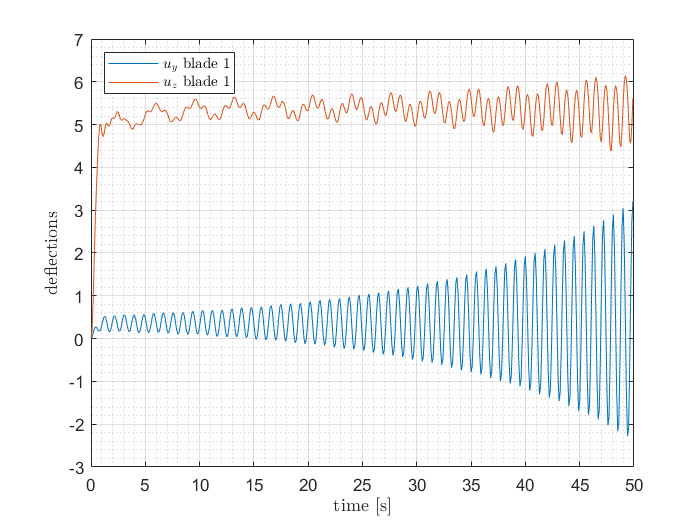

% Deflections on blade 1 over time
plot(time, u_blade_y(18,:), time, u_blade_z(18,:))
grid on; grid minor;
legend({'$u_y$ blade 1','$u_z$ blade 1'},"Interpreter","latex","Location","northwest")
xlabel('time [s]',"Interpreter","latex")
ylabel('deflections',"Interpreter","latex")

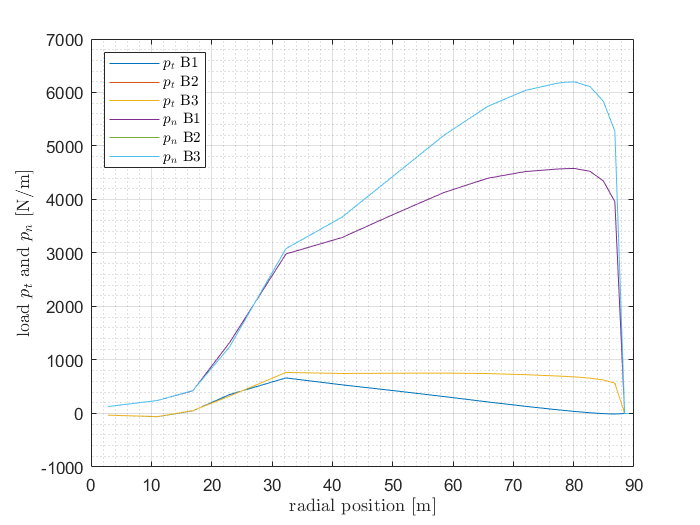



%Final load distribution
plot(r,pt(:,1,nt_max),r,pt(:,2,nt_max),r,pt(:,3,nt_max),r,pn(:,1,nt_max),r,pn(:,2,nt_max),r,pn(:,3,nt_max))
grid on; grid minor
legend({'$p_t$ B1','$p_t$ B2','$p_t$ B3','$p_n$ B1','$p_n$ B2','$p_n$ B3'},"Interpreter","latex","Location","northwest")
xlabel('radial position [m]',"Interpreter","latex")
ylabel('load $p_t$ and $p_n$ [N/m]',"Interpreter","latex")

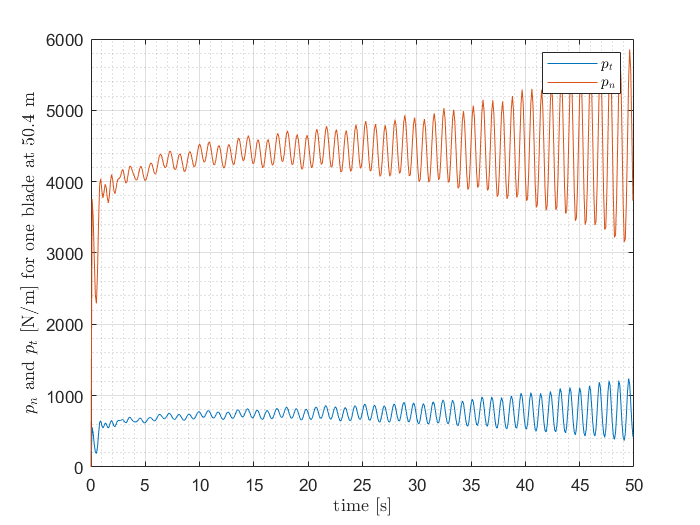



%Variation in time of the loads pt and pn for a given r
pt_1 = zeros(nt_max,1);
pn_1 = zeros(nt_max,1);
for i=1:nt_max
    pt_1(i) = pt(7,1,i); %Vector for one blade in time
    pn_1(i) = pn(7,1,i); %Vector for one blade in time
end
plot(time,pt_1,time,pn_1)
xlabel('time [s]',"Interpreter","latex")
ylabel('$p_n$ and $p_t$ [N/m] for one blade at 50.4 m',"Interpreter","latex")
legend({'$p_t$','$p_n$'},"Interpreter","latex")
grid on; grid minor;

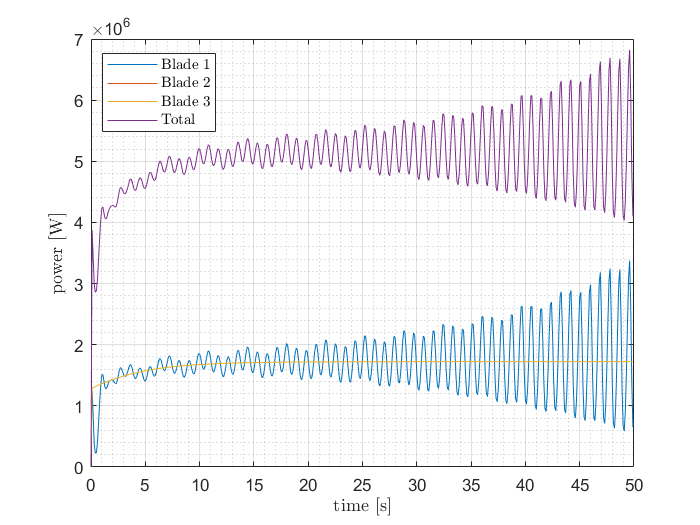


%Variation of power in time
plot(time,P1,time,P2,time,P3,time,P_total)
grid on; grid minor;
legend({'Blade 1','Blade 2','Blade 3','Total'},"Interpreter","latex","Location","best")
xlabel('time [s]',"Interpreter","latex")
ylabel('power [W]',"Interpreter","latex")

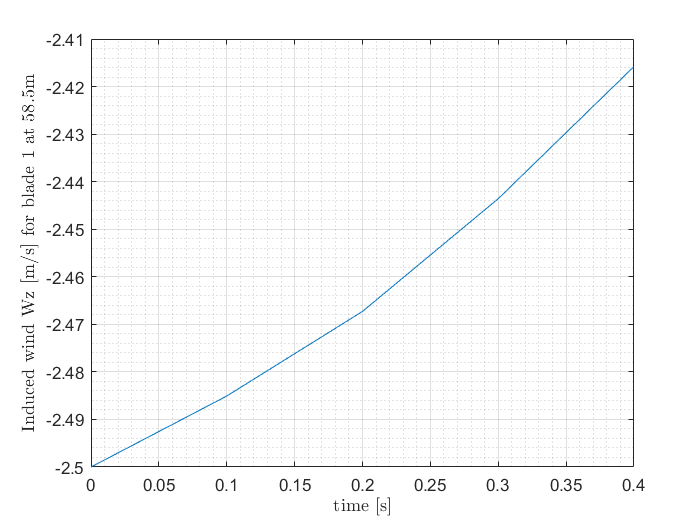


Pave = mean(P_total(5:end));
Pmax = max(P_total(5:end));

%Variation of Wz at 58.5m for blade 1
Wz_1=zeros(nt_max,1);
for i=1:nt_max
    Wz_1(i) = Wz(8,1,i); %Vector for one blade in time
end

plot(time(1:5),Wz_1(1:5))
grid on; grid minor;
xlabel('time [s]',"Interpreter","latex")
ylabel('Induced wind Wz [m/s] for blade 1 at 58.5m',"Interpreter","latex")

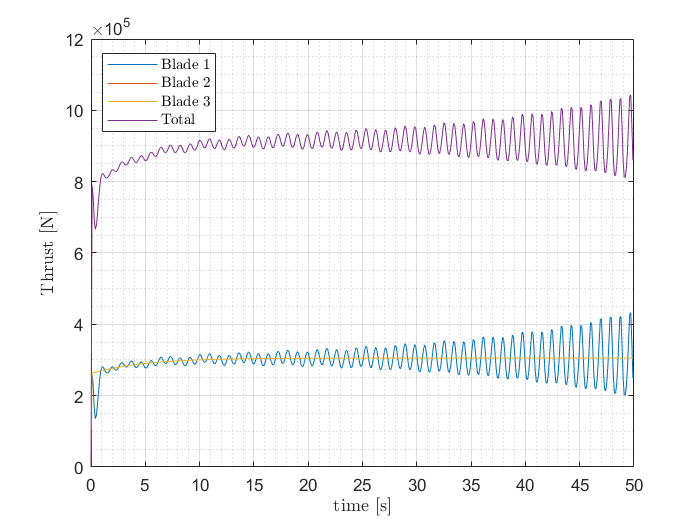


% Variation of thrust in time
plot(time,T1,time,T2,time,T3,time,T1+T2+T3)
grid on; grid minor;
legend({'Blade 1','Blade 2','Blade 3','Total'},"Interpreter","latex","Location","best")
xlabel('time [s]',"Interpreter","latex")
ylabel('Thrust [N]',"Interpreter","latex")


Tave = mean(T_total(5:end));
Tmax = max(T_total(5:end));

% Plots for PI pitch controler
%plot(time, omega(2:end))
% plot(r, pt(:,1,2),r, pt(:,1,3),r, pt(:,1,4),r, pt(:,1,5),r, pt(:,1,6),r, pt(:,1,7),r, pt(:,1,8))


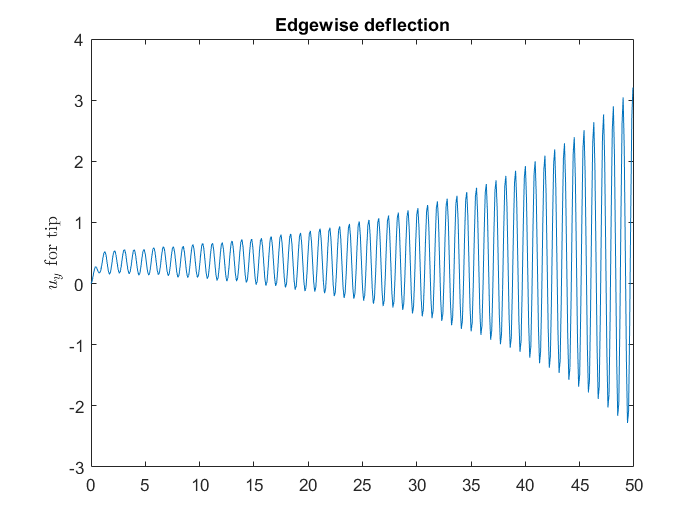

% Plot deflection for y and z
plot(time, u_blade_y(18,:));
ylabel('$u_y$ for tip',"Interpreter","latex")
title('Edgewise deflection')

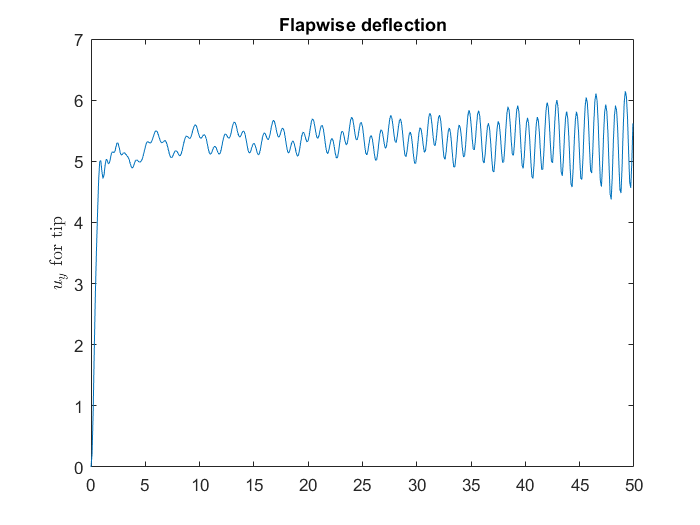


plot(time, u_blade_z(18,:));
ylabel('$u_y$ for tip',"Interpreter","latex")
title('Flapwise deflection')


plot(time, u_tow_spring)
ylabel('$u_{tower}$ at hub height',"Interpreter","latex")


    



%% Plot PSD

t_start_PSD = 0; % removes the first 70 seconds (transient)
t_end_PSD = Inf;
k_start_PSD = find(time>=t_start_PSD, 1, 'first');
k_end_PSD = find(time<=t_end_PSD, 1, 'last');
timesim_PSD = time(k_start_PSD:k_end_PSD); % transient removed
sampling_frequency = 1/dt;
nyquist_frequency = sampling_frequency/2;
n_parts_PSD = 4; %cuts the timeseries in 4 parts, this can be changed
window = hann(round(length(timesim_PSD)/n_parts_PSD), 'periodic');
noverlap = round(length(window)/2);
nperseg = length(window);
nfft = nperseg;
% Apply Welch's method
uztip = u_blade_z(18,:); 
uztipmean = mean( uztip(k_start_PSD:k_end_PSD) );
[pow_PSD_uztip, frequency_uytip] = pwelch( uztip(k_start_PSD:k_end_PSD) - uztipmean, window, ...
 noverlap, nfft, sampling_frequency, 'psd');



toc 

Elapsed time is 22.585564 seconds.
